# Lab 4: Pendulum Experiment

Pendulum Released at 30°

load('30_deg.log') % read data

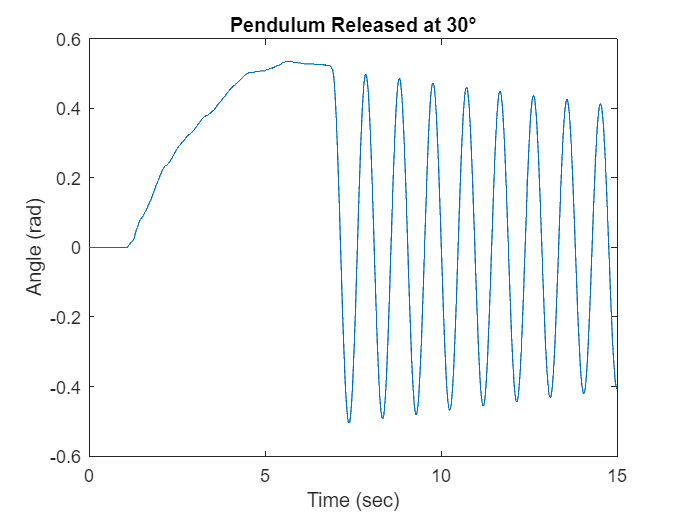

% parse data into vectors
time = X30_deg(:, 1);
encoder = X30_deg(:, 2);

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

time = time - 33; % start at t=0

interval = find(time > 0 & time < 15); % set interval

% plot data
plot(time(interval), radians(interval))
title("Pendulum Released at 30°")
xlabel("Time (sec)")
ylabel("Angle (rad)")

Pendulum Released at 15°

load('15_deg.log') % read data

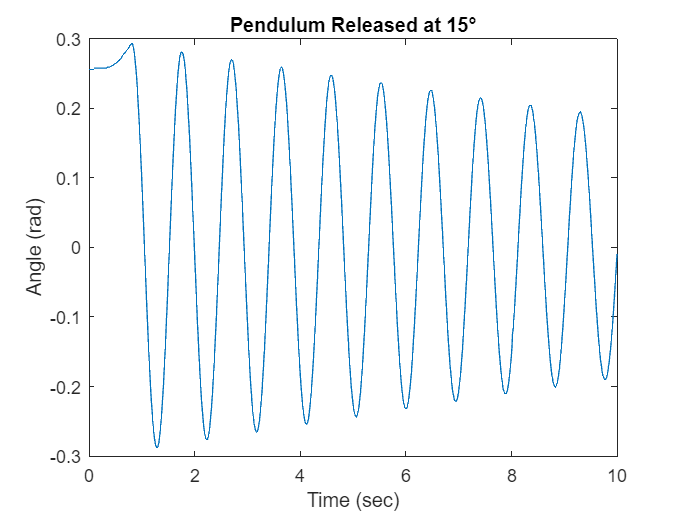

% parse data into vectors
time = X15_deg(:, 1);
encoder = X15_deg(:, 2);

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

% start a little before drop height
start = find(radians == max(radians), 1) - 100;
time = time - time(start);

interval = find(time > 0 & time < 10); % set interval

% plot data
plot(time(interval), radians(interval))
title("Pendulum Released at 15°")
xlabel("Time (sec)")
ylabel("Angle (rad)")

Pendulum Released at 20°

X20_deg = readtable('20_deg.log'); % read data

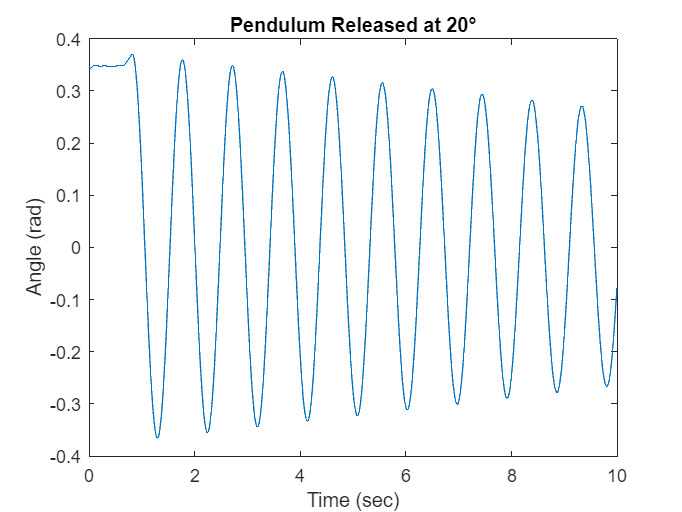

% parse data into vectors
time = X20_deg.Var1;
encoder = X20_deg.Var2;

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

% start a little before drop height
start = find(radians == max(radians), 1) - 100;
time = time - time(start);

interval = find(time > 0 & time < 10); % set interval

% plot data
plot(time(interval), radians(interval))
title("Pendulum Released at 20°")
xlabel("Time (sec)")
ylabel("Angle (rad)")